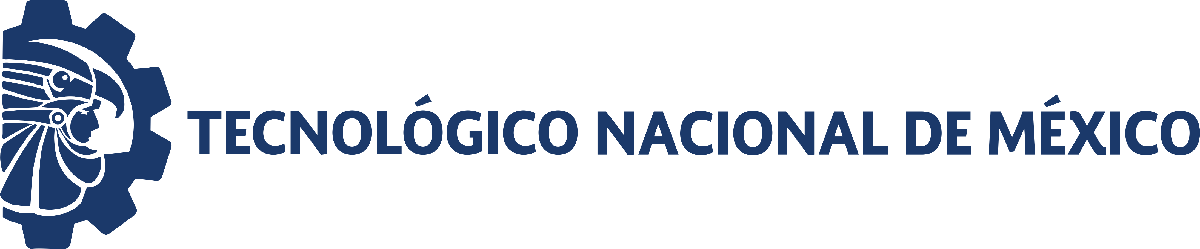                                 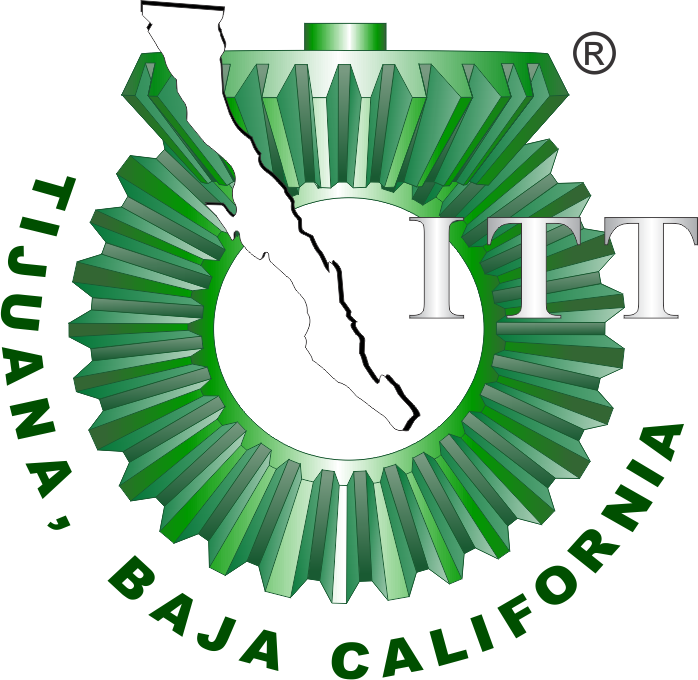

# Práctica Tres: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

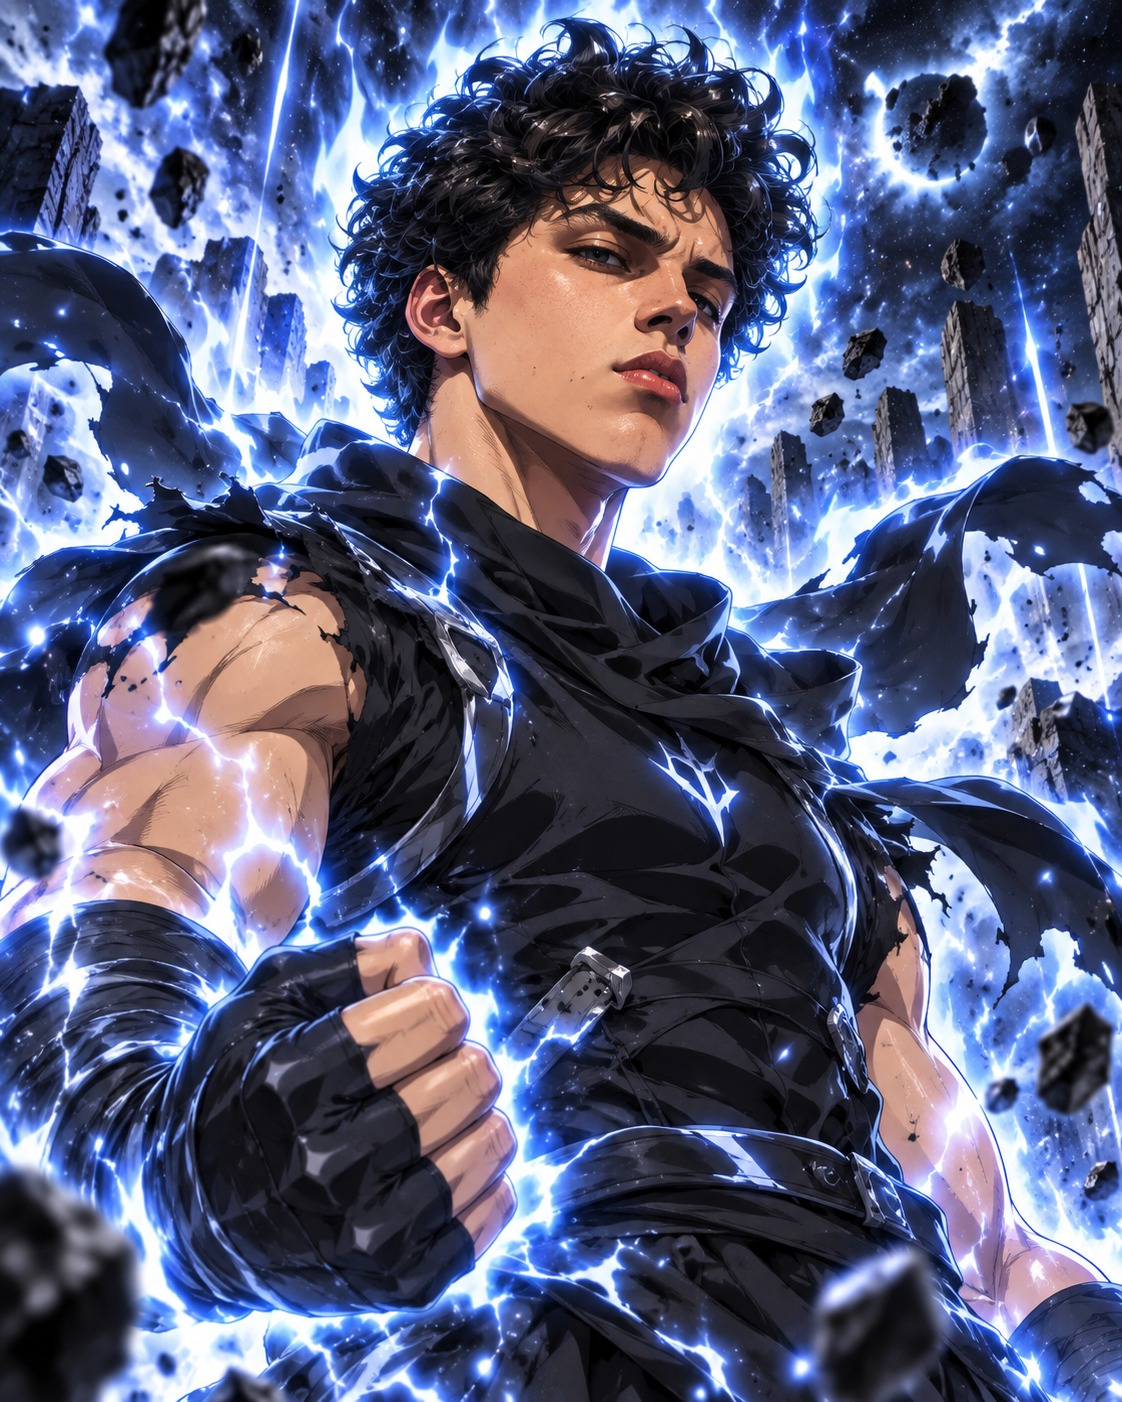

Nombre del alumno: Castro Alcántar Daniel Hiram

Número de control: **23212184**

Correo institucional: **l23212184@tijuana.tecnm.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('elsistema.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep ='1e-3';

### Respuesta al escalón

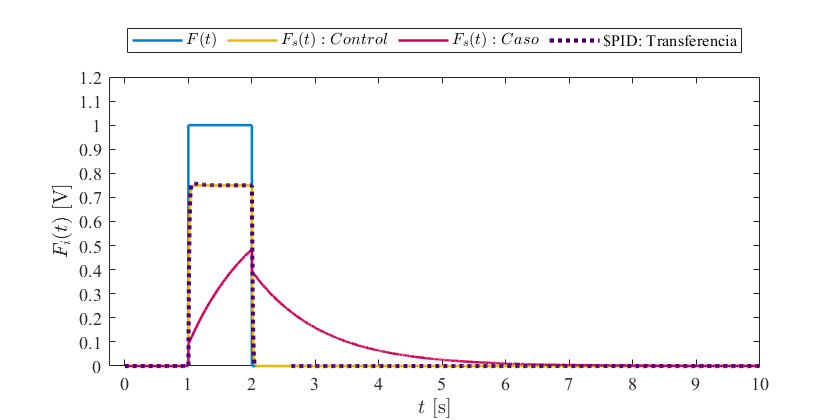

X = sim('elsistema.slx',parameters);
plotsignals(X.t,X.F,X.Fsx,X.FsY,X.PID,'simulink')

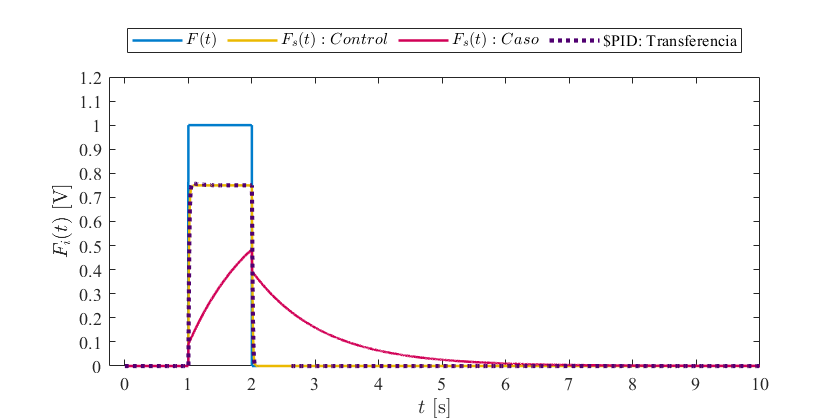

dt=1e-3;
t=(0:dt:10)';
F= zeros(length(t),1); F(1/dt:2/dt) = 1;
PID= interp1(X.t, X.PID, t, 'previous');

par_control = [0.25,10e-6,100e-6, 100];
par_caso = [0.25,10e-6,100e-6,10e3];
Fs_control = musculoesqueletico(par_control, F,t);
Fs_caso = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys')

function Fs = musculoesqueletico(par,F,t)
    alpha = par(1); Cs= par(2); Cp= par(3); R= par(4); dt=t(2);
    n= round(t(end)/dt);
    x= zeros(length(t),1); x(1)=0;
    Fs= zeros(length(t),1); Fs(1)=0;
    for i = 1:n
        x(i+1) = x(i)+((F(i)-x(i))/(R*(Cp+Cs)))*dt; %EDO
        Fs(i+1)= Cs*F(i)/(Cp+Cs)+(1 - alpha -Cs/(Cp+Cs))*x(i); %Función
    end
end



## Funcion: Respuesta de la simulacion

function plotsignals(t,F,Fsx,FsY,PID,name)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    ctrl1 = [0, 125, 204]/255;
    ctrl2 = [235,185,0]/255;
    ctrl3 = [209,0,86]/255;
    ctrl4 = [80,0,113]/255;
    order = [ctrl1;ctrl2;ctrl3;ctrl4]; colororder(order)
    
    plot(t,F,'-','Linewidth',1.5,'Color',ctrl1)
    plot(t,Fsx,'-','Linewidth',1.5,'Color',ctrl2)
    plot(t,FsY,'-','Linewidth',1.5,'Color',ctrl3)
    plot(t,PID,':','Linewidth',2.5,'Color',ctrl4)
    L = legend('$F(t)$','$F_{s}(t):Control$','$F_{s}(t):Caso$','$PID: Transferencia');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F_i (t)$ [V]','interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)
    ylim([0 1.2]); yticks(0:0.1:1.2)



    exportgraphics(gcf,['_matlab',name,'.pdf'],'ContentType','vector')


end